# Project 9 (Rocket Engines and Temperature)

8.5 in book

%{
t
   originally from 
Author: Tori Testa
Version: 1.0
Date: 2026-04-04
Purpose:
   -
Input:
   -
Output:
   -
Engineering Algorithems:
   -
MATLAB tools/functions:
   -
Reflection
   -
%}

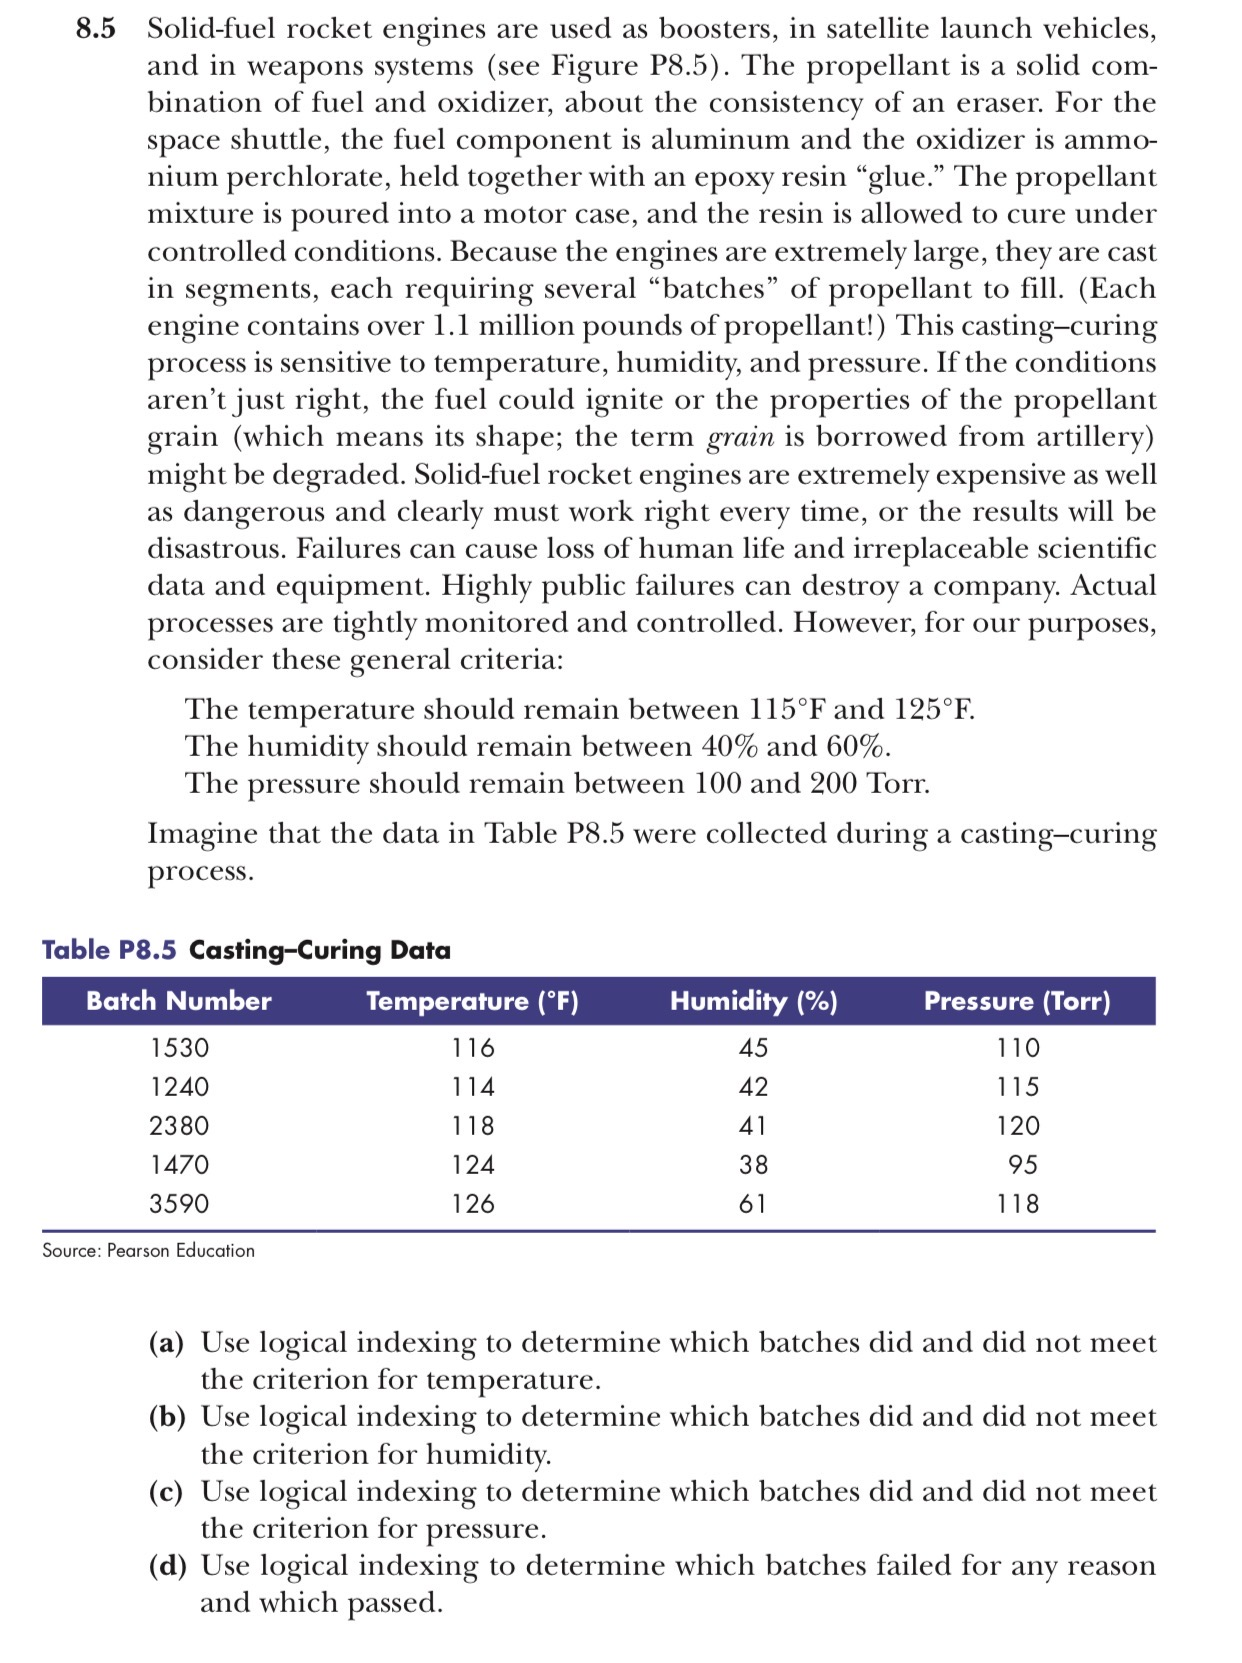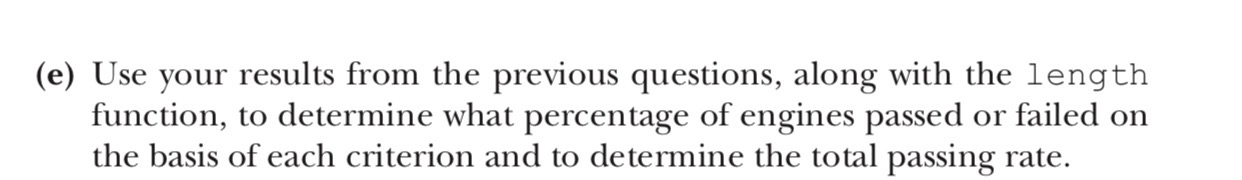

clc
clear

 % defines the variables from the data imported
readtable('casting_curing');
batch = casting_curing.batchNumber % defines batch number from the data

batch =         1530
        1240
        2380
        1470
        3590


temp = casting_curing.temperature % defines the temperature (fahrenheit) from the data

temp =    116
   114
   118
   124
   126


h = casting_curing.humidity % defines the humidity percentage from the data

h =     45
    42
    41
    38
    61


p = casting_curing.pressure % defines the pressure (torr) from the data

p =    110
   115
   120
    95
   118


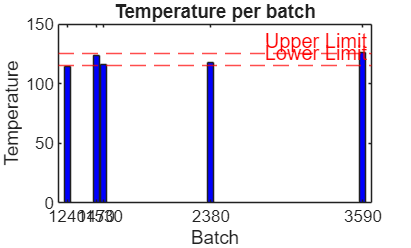

% creates a bar graph for temperature criteria
bar(batch, temp, 'blue') 
hold on % allows for multiple things to be plotted on same graph
yline(115, '--r', 'Lower Limit'); % creates a line to represent the lower temperature criteria value
yline(125, '--r', 'Upper Limit'); % creates a line to represent the upper temperature criteara value
title('Temperature per batch') % titles the plot
xlabel('Batch') % labels the x axis
ylabel('Temperature') % labels teh y axis
hold off % allows for multiple to be plotted on the same graph

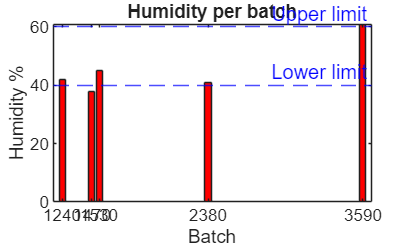

% bar chart for humidity criteria
bar(batch, h, 'red')
hold on
yline(40, '--b', 'Lower limit')
yline(60, '--b', 'Upper limit')
title('Humidity per batch')
xlabel('Batch')
ylabel('Humidity %')
hold off

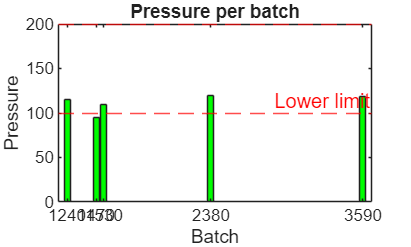

% bar chart for pressure criteria
bar(batch, p, 'green')
hold on
yline(100, '--r', 'Lower limit')
yline(200, '--r', 'Upper limit')
title('Pressure per batch')
xlabel('Batch')
ylabel('Pressure')
hold off

% determine which batches did/didn't meet temperature criteria
temp_ok = (temp >= 115) & (temp <= 125);
temp_meet= batch(temp_ok);
temp_fail= batch(~temp_ok);
disp('Batches that meet the temperature criteria:')

Batches that meet the temperature criteria:


disp(temp_meet)

        1530
        2380
        1470



disp('Batches that fail to meet temperature criteria:')

Batches that fail to meet temperature criteria:


disp(temp_fail)

        1240
        3590



% determine which batches did/didn't meet humidity criteria
h_ok = (h >= 40) & (h <= 60);
h_meet = batch(h_ok);
h_fail = batch(~h_ok);
disp('Batches that meet the humidity criteria:')

Batches that meet the humidity criteria:


disp(h_meet)

        1530
        1240
        2380



disp('Batches that fail to meet the humidity criteria:')

Batches that fail to meet the humidity criteria:


disp(h_fail)

        1470
        3590



% determine which batches did/didn't meet pressure criteria
p_ok = (p >= 100) & (p <= 200);
p_meet = batch(p_ok);
p_fail = batch(~p_ok);
disp('Batches that meet the pressure criteria:')

Batches that meet the pressure criteria:


disp(p_meet)

        1530
        1240
        2380
        3590



disp('Batches that fail to meet the pressure criteria:')

Batches that fail to meet the pressure criteria:


disp(p_fail)

        1470



% determine which batches failed for any reason or passed
all_ok = p_ok & h_ok & temp_ok;
meet = batch(all_ok);
fail = batch(~all_ok);
disp('Batches that passed:')

Batches that passed:


disp(meet)

        1530
        2380



disp('Batches that failed:')

Batches that failed:


disp(fail)

        1240
        1470
        3590



% determine the total passing rate
passRate = length(batch(all_ok))/length(batch);
passPercent = passRate * 100;
fprintf('%g percent of engines passed based on the criteria', passPercent)

40 percent of engines passed based on the criteria

function [start, incr, stop] = UserEnter
start = input('Temperature of your batch:');
if start < 0
    start = 115;
end
incr = input('Humidity (%) of your batch:');
if incr < 0
    incr = 40;
end
stop = input('Pressure of your batch:');
if stop < 0
    stop = 100;
end
end

% Prompt user for new batch parameters
[Temp, H, P] = UserEnter();
if (P >= 100) && (P <= 200) && (H >= 40) && (H <= 60) && (Temp >= 115) && (Temp <= 125)
    disp('This batch passes based on the criteria.')
else (P < 100) && (P > 200) && (H < 40) && (H > 60) && (Temp < 115) && (Temp > 125)
    disp('This batch failed to meet the necessary criteria.')
end

This batch passes based on the criteria.
